# Scan Detector Plotter

## Directory and Internal Libraries/Functions

Sets paths easily to run, calling functions that import different data types

clear
clf
cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Plotters\201029 xDBL Scan Plotting'
addpath( 'C:\Users\johns\Documents\Github\QEM-MATLAB', ...  % LT Spice output response
    'G:\My Drive\Projects');

% Recursive addpath
addpath(genpath('G:\My Drive\Projects\xDBL DoublePass'));

load('ImpVariables.mat')


## Return Home

cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\Plotters\201029 xDBL Scan Plotting'

## Jump to Data Folder

%cd 'G:\My Drive\Projects\xDBL DoublePass\PN Junction Exp\201029 xDBL CleavedScanTest\RawScanData'

## Load Data

clear
clf
load data.mat
% plot(data.a1(:,1),data.a1(:,2))
% plot(data.a2(:,1),data.a2(:,2))
% plot(data.a3(:,1),data.a3(:,2))

scan5kV = data.a2

scan5kV = 	1.0e+04 *

         0    0.0000
    0.0264    0.0000
    0.0528    0.0000
    0.0792    0.0000
    0.1056    0.0000
    0.1320    0.0000
    0.1584    0.0000
    0.1848    0.0000
    0.2112    0.0000
    0.2376    0.0000


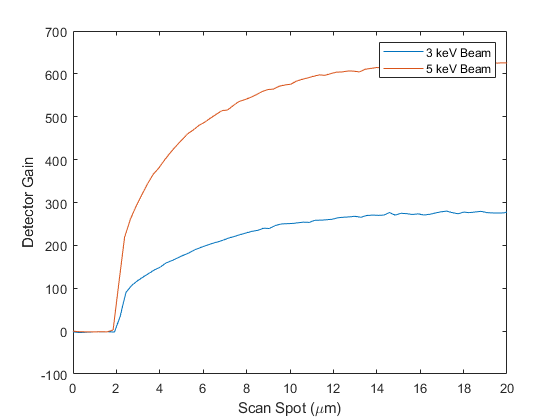

scan5kV_odd = data.a3;
scan3kV = data.a1;

readScan = scan3kV;
readScan(:,2) = - readScan(:,2) + readScan(1,2); %Normalizes and flips sign
readStart = 1;
readEnd = 78;
readScan = readScan(readStart:readEnd,:);
deriv = (readScan(1:end-1, 2) - readScan(2:end,2));

plotShift = 0.2;

figure(1)
plot(readScan(:,1)/1e3-plotShift,readScan(:,2)/(10e-12))
xlabel('Scan Spot (\mum)')
ylabel('Detector Gain')
xlim([0 20])

figure(2)
plot(readScan(1:end-1,1)/1e3-plotShift,deriv*1e9)
title('Derivative of Scan')
xlabel('Scan Spot (\mum)')
ylabel('Current Change (nA)')
xlim([0 20])


readScan = scan5kV;
readScan(:,2) = - readScan(:,2) + readScan(1,2); %Normalizes and flips sign
readStart = 1;
readEnd = 78;
readScan = readScan(readStart:readEnd,:);
deriv = (readScan(1:end-1, 2) - readScan(2:end,2));

figure(1)
hold on
plot(readScan(:,1)/1e3,readScan(:,2)/(10e-12))
xlabel('Scan Spot (\mum)')
ylabel('Detector Gain')
legend(['3 keV Beam'; '5 keV Beam'])
hold off

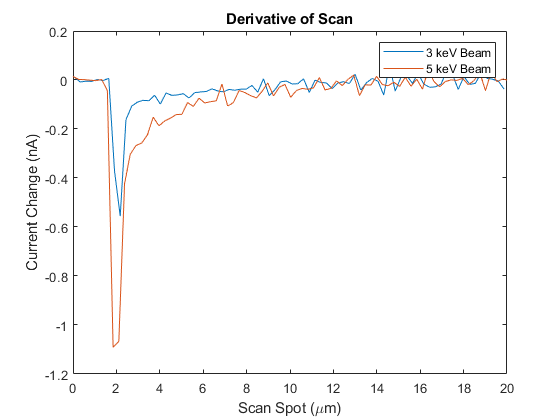


figure(2)
hold on
plot(readScan(1:end-1,1)/1e3,deriv*1e9)
title('Derivative of Scan')
xlabel('Scan Spot (\mum)')
ylabel('Current Change (nA)')
legend(['3 keV Beam'; '5 keV Beam'])

## Plot Full    

% figure(1)
% hold on
% plot(readScan(:,1)/1e3,readScan(:,2)/(10e-12))
% xlabel('Scan Spot (\mum)')
% ylabel('Detector Gain')
% hold off
% 

## Plot Derivative

% hold on
% figure(2)
% plot(readScan(1:end-1,1),deriv*1e9)
% title('Derivative of Scan')
% xlabel('Scan Spot (\mum)')
% ylabel('Current Change (nA)')
% hold off